**General Information**

ATOC Class creates an instance of an air traffic control within a simulation. It is responsible for monitoring air traffic and notify any behavior that doesn't follow that air traffic rules. 

An object of ATOC allows insights into what is happening within the simulation by looking at multiple different aspects of the simulation through tracking information about the lane based reservations, UAS telemetry data, and sensory data. 

**Setting Up for Simulation**

This section is just for setting up the simulation, radar objects, and uas object. In order to display the functionality of the atoc object. 

rng(0);
%%%%%%%%%%%%%%% LANE BASED SYSTEM SETUP %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
lbsd = LBSD.genSampleLanes(10, 15);

%%%%%%%%%%%%%%%%% SIMULATION SETUP %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
sim = Sim();

%%%%%%%%%%%%%%%%% RADAR SETUP %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
radarStruct = sim.LEM_radars_placement_coverage(lbsd, 30, eye(3), pi/4);
for index = 1:size(radarStruct, 1)
    id = radarStruct(index).id; % Identification
    pos = [radarStruct(index).x, radarStruct(index).y, radarStruct(index).z]; % Location
    range = radarStruct(index).max_range; % max radar range
    apexAngle = radarStruct(index).phi; % beam width angle
    dir = [radarStruct(index).dx, radarStruct(index).dy, radarStruct(index).dz]; % unit dir vector
    radar = RADAR(pos, range, apexAngle, dir, id, lbsd); % Creation Radar object
    radar.time = 0; % Set radar time
    sim.subscribe_to_tick(@radar.handle_events);
    sim.radar_list = [sim.radar_list; radar];
end

%%%%%%%%%%%%%%%%% UAS SETUP %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
list_uas = [];
lane_ids = lbsd.getLaneIds;
for num = 1:10
    laneIndex = randi(length(lane_ids));
    ids = lbsd.getLaneVertexes(lane_ids(laneIndex));
    pos = lbsd.getVertPositions(ids(1, :));
    dis = norm(pos(2, :) - pos(1, :));
    start_time = randi(100);
    end_time = start_time + randi(20) + 5;
    speed = dis/(end_time - start_time);
    lbsd.makeReservation(lane_ids(laneIndex), start_time, end_time, speed, 5, num2str(num));
    uas = UAS(num2str(num));
    uas.gps.lon = pos(1,1);
    uas.gps.lat = pos(1,2);
    uas.gps.alt = pos(1, 3);
    sim.uas_list = [sim.uas_list; uas];
    velocity = (pos(2, :) - pos(1, :))/(end_time - start_time);
    list_uas = [list_uas; struct("UAS", uas, "start", start_time, "end", end_time, "velocity", velocity)];
end

**Creation of ATOC Object**

To create an atoc object, there is only one constructor which takes the parameter of the lbsd handle object. 

%%%%%%%%%%%%%%%%  ATOC SETUP %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
atoc = ATOC(lbsd);

The data structures that each atoc object contains is a couple of tables that display telemetry data, sensory data, and rogue behaviors. In addition, atoc uses a hashtable to store simulation data for each lane, with the lane being the key to access the information. Other data structures are used to store figure handles for the continuous graphs that can be formed from the data. 

%%%%%%%%%%%%% DISPLAYING THE DATA STRUCTURES %%%%%%%%%%%%%%%%%%%%%%%%
disp("Telemetry Data");

Telemetry Data


disp(atoc.telemetry);

    ID        pos        speed    time
    __    ___________    _____    ____

    ""    0    0    0      0       0  



disp("Sensory Data");

Sensory Data


disp(atoc.radars);

    ID        pos        speed    time
    __    ___________    _____    ____

    ""    0    0    0      0       0  



disp("Overall Density Information");

Overall Density Information


disp(atoc.overallDensity);

       data: [0 0]
    fHandle: [1×1 Figure]
    pHandle: [1×1 Line]



disp("Lane Data Structure");

Lane Data Structure


disp(atoc.laneData);

  Map with properties:

        Count: 24
      KeyType: char
    ValueType: any



disp("Individual Lane");

Individual Lane


disp(atoc.laneData("1"));

          pos: [5 -12.0711 15 -5 -12.0711 15]
      density: [1×2 table]
    telemetry: [1×6 table]
      sensory: [1×4 table]



disp("Telemetry Data");

Telemetry Data


disp(atoc.laneData("1").telemetry);

    ID        pos        time    del_speed    del_dis    projection
    __    ___________    ____    _________    _______    __________

    ""    0    0    0     0          0           0           0     



disp("Sensory Data");

Sensory Data


disp(atoc.laneData("1").sensory);

    ID        pos        speed    time
    __    ___________    _____    ____

    ""    0    0    0      0       0  



disp("Density")

Density


disp(atoc.laneData("1").density);

    number    time
    ______    ____

      0        0  



**Subscribing To Other Events**

There is a couple of events that atoc needs to subscribe to inorder to function properly. The first thing is atoc needs to subscribe to the simulation tick event. Atoc using the tick event to do the rogue detection analysis as well the overall/individual lane density analysis. The other event the atoc needs to subscribe to is uas telemetry event. Atoc uses this event to store all of the telemetry information that is happening in the simulation as well as this information is used during the tick simulation. The next event that atoc needs to be describe to is the lbsd objects new reservation broadcast. Atoc uses this information to update its handle of all of the reservations in the simulation. The final event that the atoc object needs to subscribe to is the radars detection event. Atoc uses this information to store all the sensory information that is happening during the simulation as well as finding rogue behavior during the tick event.

%%%%%%%%%%%%%%% SUBSCRIBE TO TICK %%%%%%%%%%%%%%%%%%%%%%%%%%
sim.subscribe_to_tick(@atoc.handle_events);

%%%%%%%%%%%%%%% SUBSCRIBE TO TELEMETRY %%%%%%%%%%%%%%%%%%%%%
for num = 1:length(sim.uas_list)
    uas = sim.uas_list(num);
    uas.subscribeToTelemetry(@atoc.handle_events);
end

%%%%%%%%%%%%%%% SUBSCRIBE TO NEW RESERVATIONS %%%%%%%%%%%%%%
lbsd.subscribeToNewReservation(@atoc.handle_events);

%%%%%%%%%%%%%%% SUBSCRIBE TO DETECTION %%%%%%%%%%%%%%%%%%%%%
for num = 1:length(sim.radar_list)
    radar = sim.radar_list(num);
    radar.subscribe_to_detection(@atoc.handle_events);
end

**Running the Simulation**

This next segment runs a small simulation with 10 uas that has been randomly generated reservations. During this simulation the continuous overall density graph will display. 

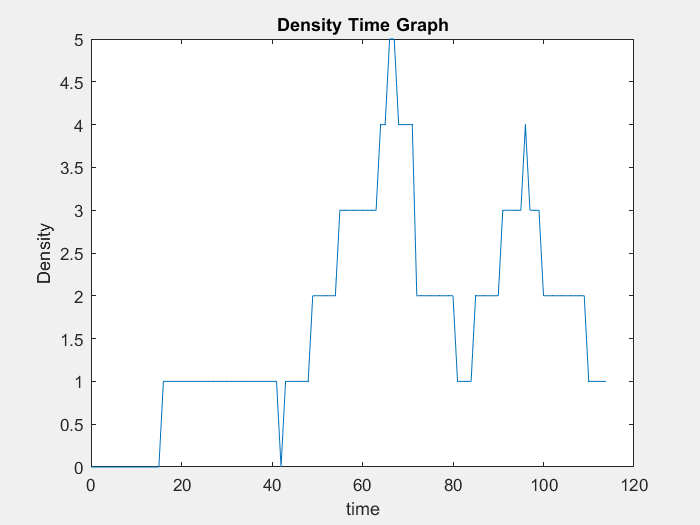

totalEnd = max([list_uas(:).end]);
atoc.time = 0;

atoc.showDensity();
% Run the simulation
while(atoc.time < totalEnd)
    sim.uas_list = [];
    removeIndex = [];
    for lane1 = 1:length(list_uas)
        s = list_uas(lane1);
        if(s.end < atoc.time)
            removeIndex = [removeIndex; lane1];
        elseif (s.start <= atoc.time)
            uas = s.UAS;
            r = -.5 + rand(1,3);
            uas.gps.lon = uas.gps.lon + s.velocity(1,1);% + r(1);
            uas.gps.lat = uas.gps.lat + s.velocity(1,2);% + r(2);
            uas.gps.alt = uas.gps.alt + s.velocity(1,3);% + r(3);
            uas.gps.commit();
            sim.uas_list = [sim.uas_list; uas];
        end
    end
    list_uas(removeIndex) = [];
    sim.step(1);
end

The next information of telemetry data that is presented through graphs would be looking at the density of UAS through the lane system. There are two graphs that will help with the overview of this data. One looks at the number of UAS at a given time in all of the lanes, whereas the other graph will look at the density with a specific lane that was given. Both of these graphs will allow for a time interval that will allow for specfic time or no time interval to allow to see over the whole simulation.

%%%%%%%%%%%%%%% SHOWING LANE 1 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%% SHOWING LANE 5 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%% SHOWING LANE 10 %%%%%%%%%%%%%%%%%%%%%%%%%%%%


**Visualing Telemetry Data**

There are multiple different ways to visual telemetry data to track UAS behavior with respect to its planned trajectory. 

The first graph that can be formed is lane trajectory which is displaying the space diagram of the UAS projected distance from the lane itself. This is supposed to be used to get a quick glance whether an object is following the given path. However, this doesn't give a percise represented of whether an objects deviation from the planned path is due to location or speed is not relatively given from this graph. 

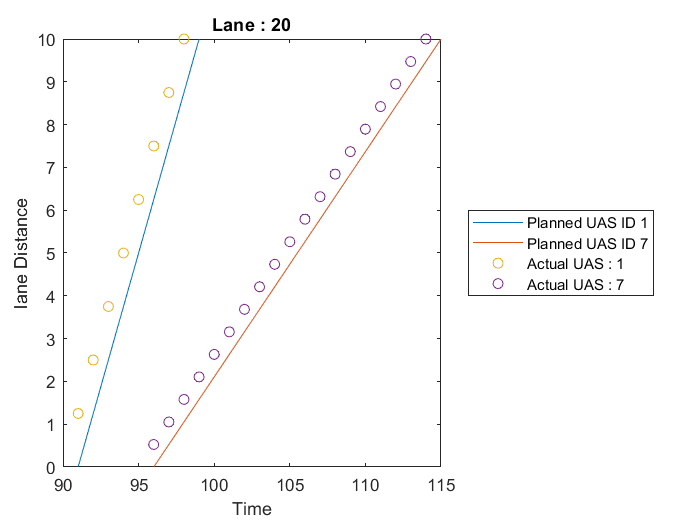

% Grab a random time interval
maxTime = 120;
minTime = 90;
time = [0 maxTime];

% Selection of certain lanes
res = lbsd.getReservations().lane_id;
lanes = res(1);
% Displays the space lane digrams
atoc.laneTrajectory(lanes, time);

Therefore, the next function is supposed to give a more specific look at the deviation between distance and speed from the telemetry data versus the planned data given a specific time interval to look at. This function takes in specific lanes that is desired to look at given a interval of time. 

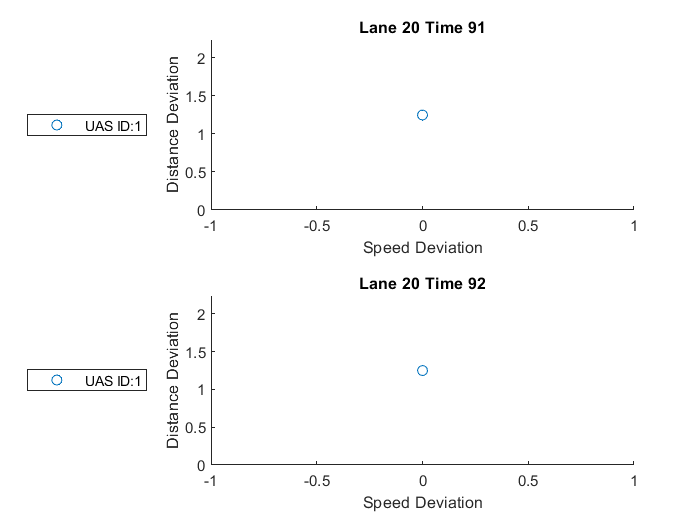

% Grabs only a small time interval to specifically look at certain data
% points.
res = lbsd.getReservations();
info = res{1, {'entry_time_s', 'exit_time_s', 'lane_id'}};
start_time = str2double(info(1));
end_time = str2double(info(2));
specific_time_interval = [start_time, start_time + (end_time - start_time)/8];
atoc.speedvsdisGraph(info(3), specific_time_interval);

I also created another function that would invoke both of the previous graphs in one function. That would allow to look at the two different graphs at the same time interval. This section is commit out to save space in the graph region.

% Function that plots the previous two funciton using just a single
% function
% res = lbsd.getReservations();
% res = res{end, {'lane_id', 'entry_time_s', 'exit_time_s'}};
% timeInterval = [str2double(res(2)), str2double(res(3))];
% laneGraphs(res(1), timeInterval);

**Flight Trajectory Graph**

Another way to visiualize the telemetry data is by looking at the total flight trajectory of the path for a single UAS flight trajectory. 

% Creatation of the Flight Trajectory Method

**Rogue Detection**

This section will show how the atoc object handles rogue uas flights in the simulation. There are only a few rogue detections